# Example: Quality Control Module 

The following example runs a simple quality control analysis on wave elevation data. The data file used in this example is stored in the [\MHKiT\examples\data](https://github.com/MHKiT-Code-Hub/MHKiT-Python/tree/master/examples/data) directory.

## Import Data

Load the data into a table. The data includes several issues, including timestamps that are out of order, corrupt data with values of -999, data outside expected range, and stagant data. The first 5 rows of data are shown below, along with a plot.

data=readtable('../examples/data/wave_elevation_data.csv');
disp(data)

     Time     probe1    probe2    probe3
    ______    ______    ______    ______

        10     24.48     28.27      1.3 
    10.002     34.48     40.27     -8.7 
    10.004     30.48     38.27    -13.7 
    10.006     12.48     24.27    -32.7 
    10.008     13.48     22.27    -21.7 
     10.01      7.48     15.27    -13.7 
    10.012      4.48     13.27    -19.7 
    10.014     -9.52     -0.73    -11.7 
    10.016      8.48     19.27    -16.7 
    10.018     -4.52      8.27    -34.7 
     10.02     16.48     27.27      5.3 
    10.022    -13.52     -0.73    -36.7 
    10.024    -13.52      0.27    -39.7 
    10.026    -15.52     -3.73    -32.7 
    10.028    -22.53    -17.73    -23.7 
     10.03    -22.52    -16.73     16.3 
    10.032      -999    -23.73      1.3 
    10.034      -999    -16.73     11.3 
    10.036      -999    -24.73     13.3 
  

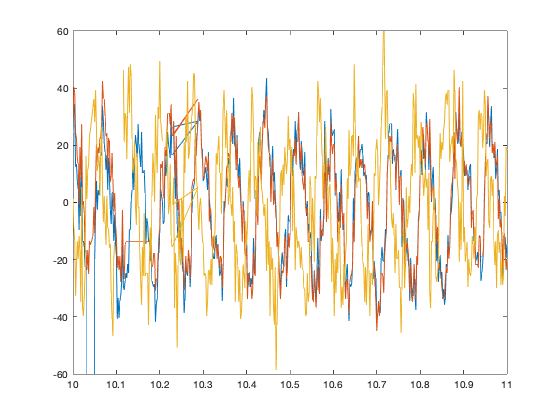

plot(data.Time,[data.probe1,data.probe2,data.probe3]);
ylim([-60 60]);

The MHKiT-Matlab QC module utilizes structures. WE need to convert the table of data into a structure. 

datast.time=data.Time;
datast.values = table2array(data(:,2:4));
datast

datast = struct with fields:
      time: [500×1 double]
    values: [500×3 double]


## Quality control tests

The following quality control tests are used to identify timestamp issues, corrupt data, data outside expected range, and stagnant data.

Each quality control tests results in the following information in a results structure:

- Cleaned data that has *NaN* in place of data that did not pass the quality control test

- Boolean mask with True/False that indicates if each data point passed the quality control test

## Check timestamp

Quality control analysis generally starts by checking the timestamp index of the data.

The follow test checks to see if 1) the data contains duplicate timestamps, 2) timestamps are not monotonically increasing, and 3) timestamps occur at irregular intervals (an interval of 0.002s is expected for this data).

If duplicate timestamps are found, the resulting structure keeps the first occurrence. If timestamps are not monotonic, the timestamps in the resulting structure are reordered.

frequency = 0.002; % define expected frequency of the data, in seconds 
results = check_timestamp(datast,frequency); % run the timestamp quality control test

The cleaned data and boolean mask are shown below. 

disp(results)

    values: [501×3 double]
      mask: [501×3 int64]
      time: [1×501 datetime]



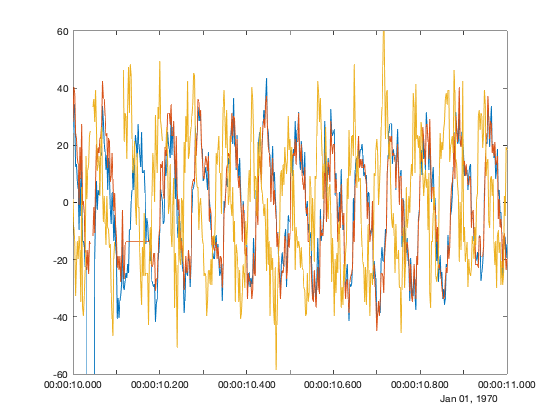

plot(results.time,results.values);
ylim([-60 60]);

## Check for corrupt data

In the following qualtiy control tests, the cleaned data from the previous test is used as input to the subsequent test. For each quality control test, a plot of the cleaned data is shown.

The quality control test below checks for corrupt data, indicated by a value of -999.

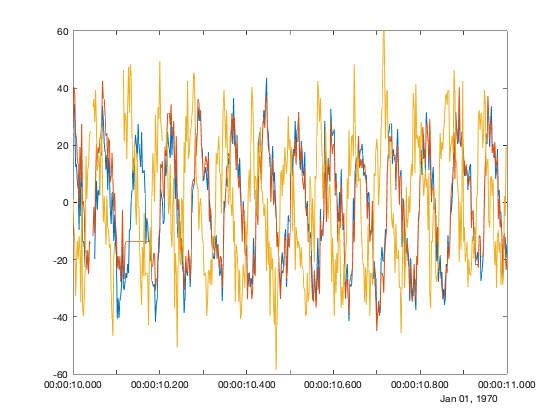

corrupt_values = {-999}; %define corrupt values

results = check_corrupt(results,corrupt_values); % run the corrupt data QC test

plot(results.time,results.values);
ylim([-60 60]);

## Check for data ourside expected range

The next quality control test checks for data that is greater than 50 or less than -50.

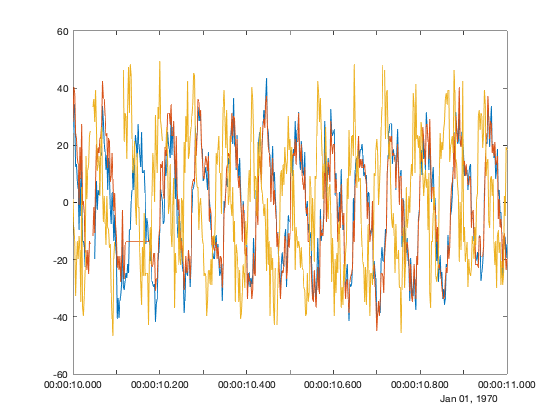

expected_bounds = [-50,50]; % define expected lower and upper bound

results = check_range(results,expected_bounds); % run expected range QC test

plot(results.time,results.values);
ylim([-60 60]);

## Check for stagnant data

The final quality control test checks for stagnant data by looking for data that changes by less than 0.001 within a 0.02 second moving window.

expected_bound = [0, NaN]; % define the lower bound (no upper bound is specified in this example)

window = 0.02; % define the moving window in seconds 

results = check_increment(results,expected_bound); % input the data, boundaries, py.None indicates apply to all columns, and window

plot(results.time,results.values);
ylim([-60 60]);